# Thickness analysis

This tutorial explains how to compute sectorized thickness metrics from OCT images.

Followed steps:

- Load OCT images into MATLAB

- Compute layer thicknesses

- Average point thickness values across sectors (ETDRS, rings...)

If you need help, feel free to reach us at **dromero@mondragon.edu**

close all; clc; clearvars;
addpath(genpath('../src'));

### Load a file

This step parses the information inside the file and computes the X, Y coordinates of each A-scan.

To analyse retinal thickness we only need the header and the segmentation data.

file = 'data/example_raster.vol';
[header, seg, ~, ~] = read_vol(file, 'get_coordinates');

X = header.X_oct;
Y = header.Y_oct;

We can check which segmented boundaries are present in the file:

disp(fields(seg)')

    {'ILM'}    {'BM'}    {'RNFL_GCL'}    {'GCL_IPL'}    {'IPL_INL'}    {'INL_OPL'}    {'OPL_ONL'}    {'ELM'}    {'MZ_EZ'}    {'OSP_IZ'}    {'IZ_RPE'}



### **Compute thickness**

We can now compute thicknesses as the difference between segmented boundaries.

We need to specify the layers to analyse as input.

Thickness values are by defaul in pixels, but can be computed in $\mu m$ if we pass the axial resolution (`scale_z`) to the function.

The output are stored in the struct `Thickness` with a field for every layer.

layers = {'TRT', 'GCIPL'};
Thickness = compute_thickness(seg, layers, header.scale_z);

TRT = Thickness.TRT;
GCIPL = Thickness.GCIPL;

### **Resample to a regular grid**

To compute averaged sector thicknesses it is convenient to have regular spatial sampling (i.e., same sampling distribution across the macula).

To achieve that we can transform our original A-Scan coordinates to a regular grid by using interpolation.

[X_new, Y_new, TRT_new] = resample_map(X, Y, TRT, 'regular', 'max_d', 3, 'n_point', 100);
[X_new, Y_new, GCIPL_new] = resample_map(X, Y, GCIPL, 'regular', 'max_d', 3, 'n_point', 100);

We can visualize the sampling grid difference

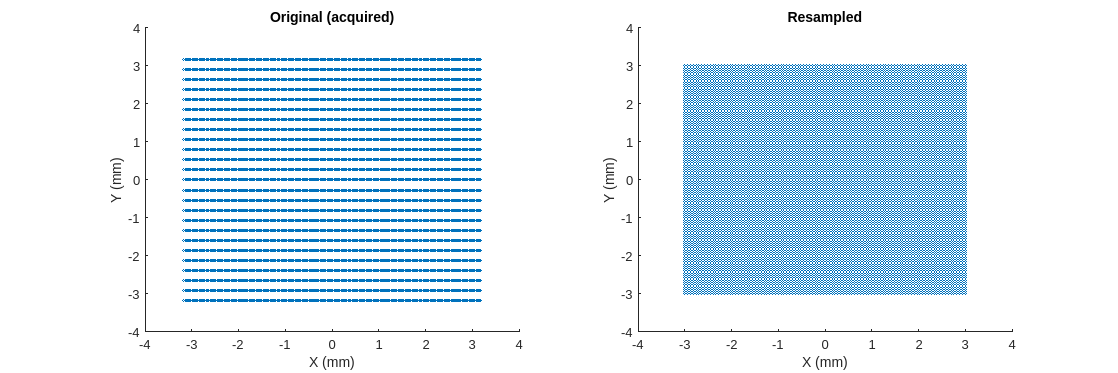

f = figure('Position', [0 0 1200 400]);
subplot(121); 
scatter(X(:), Y(:), 2); 
xlabel('X (mm)'); ylabel('Y (mm)'); title('Original (acquired)');
axis(4 * [-1 1 -1 1]);

subplot(122); 
scatter(X_new(:), Y_new(:), 2);
xlabel('X (mm)'); ylabel('Y (mm)'); title('Resampled');
axis(4 * [-1 1 -1 1]);

### **Visualize thickness maps**

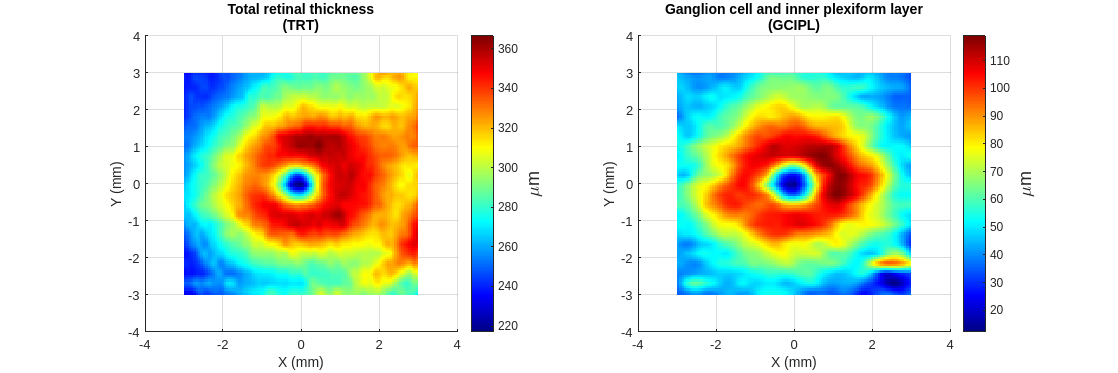

f = figure('Position', [0 0 1200 400]);
subplot(121); 
surf(X_new, Y_new, TRT_new, 'EdgeColor', 'none'); view(0, 90); 
xlabel('X (mm)'); ylabel('Y (mm)'); title({'Total retinal thickness','(TRT)'});
axis(4 * [-1 1 -1 1]);
cb = colorbar; 
cb.Label.String = '\mum';
cb.Label.FontSize = 14;

subplot(122)
surf(X_new, Y_new, GCIPL_new, 'EdgeColor', 'none'); view(0, 90); 
xlabel('X (mm)'); ylabel('Y (mm)'); title({'Ganglion cell and inner plexiform layer','(GCIPL)'});
axis(4 * [-1 1 -1 1]);
cb = colorbar;
cb.Label.String = '\mum';
cb.Label.FontSize = 14;

colormap(jet);

### Foveal location

Often, acquired images may not be correctly centered at the foveal pit (due to fixation errors).

This can result in erroneous measurement and must be corrected. To do this we need to:

- Locate the actual foveal center automatically

- Set `X`, `Y` coordinate origin to the foveal center

[x_fovea, y_fovea] = find_fovea(X, Y, TRT);

X = X - x_fovea;
Y = Y - y_fovea;

### **Sectorized thickness**

Often we are interested in average measures of the thickness maps of above.

For instance, to compute `ETDRS` sectorized we just need to:

[TRT_etdrs, Sect_etdrs]  = sectorize_map(X_new, Y_new, TRT_new, 'mean', 'etdrs');
[GCIPL_etdrs, Sect_etdrs] = sectorize_map(X_new, Y_new, GCIPL_new, 'mean', 'etdrs');

This returns the averaged numeric values: `TRT_etdrs` and a `Sect_etdrs` struct.

ETDRS sectors are: central, inner nasal, inner superior, inner  temporal, inner inferior, outer nasal, outer superior, outer temporal and outer inferior

etdrs_vars = {'C', 'IN', 'IS', 'IT', 'II', 'ON', 'OS', 'OT', 'OI'};
T = cell2table([layers' num2cell([TRT_etdrs; GCIPL_etdrs])], 'VariableNames',[{'layer'}, etdrs_vars])

T = 2×10 table
      layer        C         IN        IS        IT        II        ON        OS        OT        OI  
    _________    ______    ______    ______    ______    ______    ______    ______    ______    ______

    {'TRT'  }    273.43    349.68    348.87    329.63    343.47    326.65    304.75    290.43    293.09
    {'GCIPL'}    41.423    106.57    104.13    94.214    98.384    70.813    72.168     72.43    62.045


We can also use more advanced sectorizations

Sectors.type    = 'wedge';
Sectors.radius  = linspace(0, 3, 10);
Sectors.theta_0 = 0;
Sectors.n_angle = 20;
Sectors.n_sect  = Sectors.n_angle * (length(Sectors.radius) - 1);

[TRT_wedge, Sect_wedge]  = sectorize_map(X_new, Y_new, TRT_new, 'mean', Sectors);
[GCIPL_etdrs, Sect_wedge] = sectorize_map(X_new, Y_new, GCIPL_new, 'mean', Sectors);

### **Visualize sectorized thickness**

We can visualize arbitrary segmentations by using `plot_sectors()`

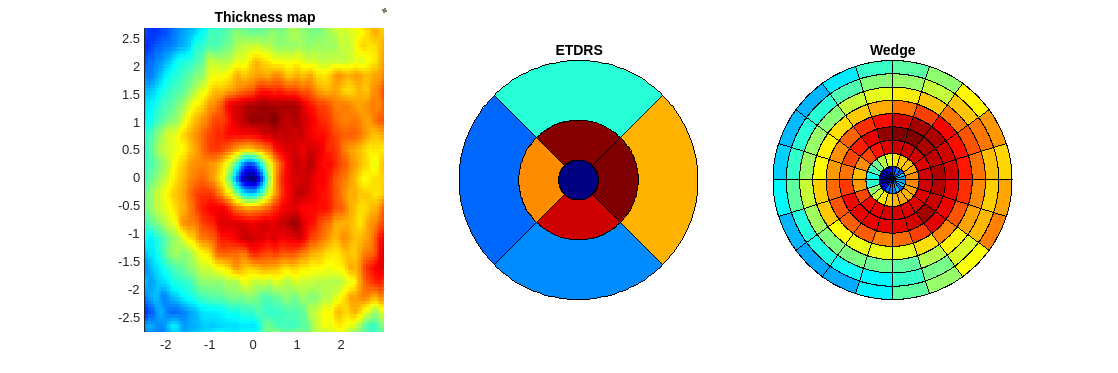

f = figure('Position', [0 0 1200 400]);

subplot(131);
surf(X_new, Y_new, TRT_new, 'EdgeColor', 'none'); view(0,90);
axis([-3 3 -3 3]);
title('Thickness map')

subplot(132);
plot_sectors(TRT_etdrs, Sect_etdrs); title('ETDRS');

subplot(133);
plot_sectors(TRT_wedge, Sect_wedge); title('Wedge');

colormap("jet")